filename = 'CueRewardSize-SPE-03-12-2020';
load([filename,'_D.mat']);

Calculate lick probability by condition(i.e. reward size)

align by cue on time and go for 3 seconds

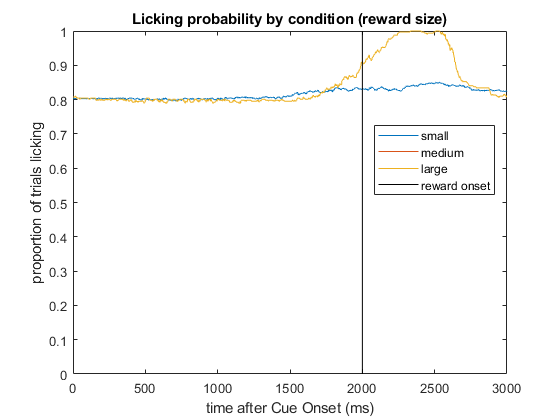

T = 3000;
lickProbability = zeros(3,T); % first count by condition
trialCount = zeros(3,1);

for trind = 1:length(D.TrialNumber)
    if ~D.Rewarded(trind) % rewarded/successful trials only
        continue;
    end
    if D.ActualRewardSize(trind)<30 % should be 20 or 21
        cond = 1;
    elseif D.ActualRewardSize(trind)<120 % should be 110 or 111
        cond = 2;
    else
        cond = 3;
    end
    trialCount(cond) = trialCount(cond) + 1;
    cueOn = D.CueOnTime(trind);
    lickingBinary = D.LickingBinary{trind};
    lickProbability(cond,:) = lickProbability(cond,:) ...
        + double(lickingBinary((cueOn+1):(cueOn+3000)))';
end

for cind = 1:3
    lickProbability(cind,:) = lickProbability(cind,:) ...
        / trialCount(cind);
end

figure;
for cind = 1:3
    plot(lickProbability(cind,:)); hold on;
end
xlabel('time after Cue Onset (ms)');
ylabel('proportion of trials licking')
line([2000,2000],[0,1],'color','k');
legend({'small','medium','large','reward onset'},'location','best');
title('Licking probability by condition (reward size)')